clear,clc;

dt = 0.0001;
Fc = 0.0006;
kt1 = 50;
kt2 = 100;


q_dot = -1:dt:1;

F1 = Fc*tanh(kt1*q_dot);
F2 = Fc*tanh(kt2*q_dot);
F5 = Fc * sign(q_dot);

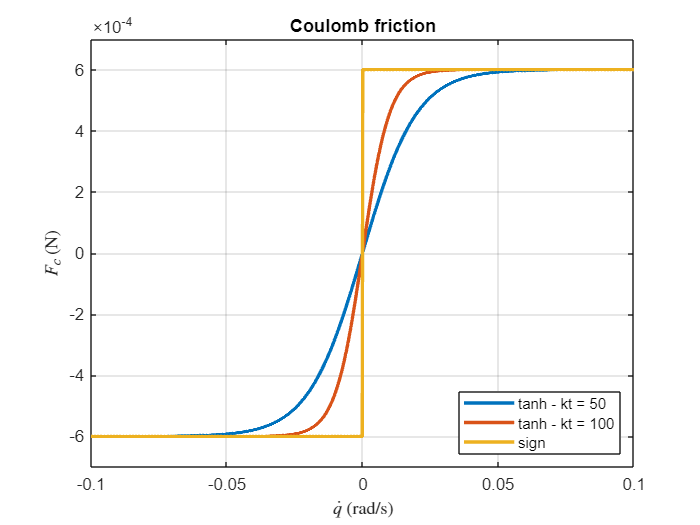

plot(q_dot, F1, q_dot, F2, q_dot, F5, "LineWidth",2);
legend(["tanh - kt = 50", "tanh - kt = 100", "sign"], "Location","southeast")
title("Coulomb friction");
xlabel("$\dot{q}$ (rad/s)", "Interpreter","latex");
ylabel("$F_c$ (N)", "Interpreter","latex");
xlim([-0.1, 0.1]);
ylim([-0.0007, 0.0007]);
grid on;

exportgraphics(gcf,'sign_vs_tanh.pdf','ContentType','vector')